# EXERCISE #1 : Build a Two Node WLAN Scenario 

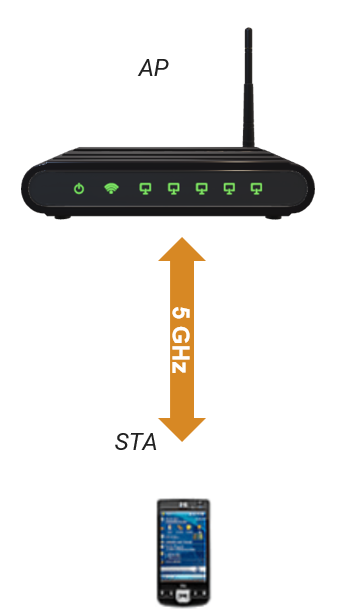

WLAN Network with one AP and one STA 

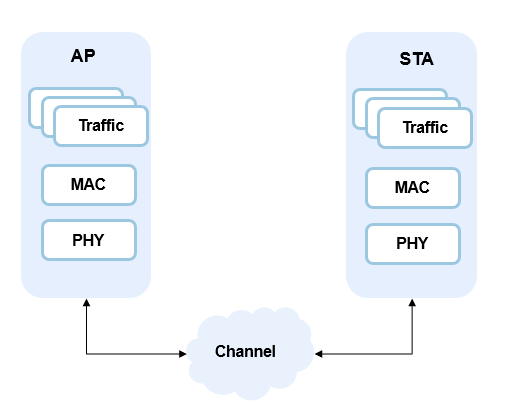

Blocks modeled in this exercise  

## A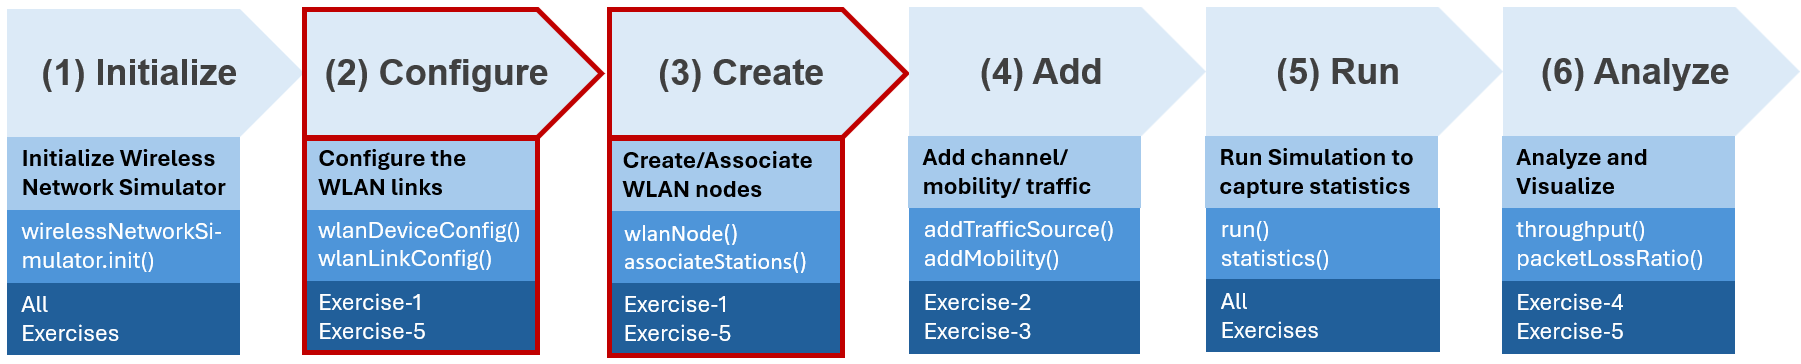

Workflow to perform WLAN Network Modeling 

#### In this exercise, you will learn how to configure and create WLAN nodes. Simulate the network capture statistics.   

Copyright 2024-2025 The MathWorks, Inc

#### Cleanup

clear;
format shortEng;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows

### General settings

- `5 GHz band`

- `20 MHz wide channel`

- `Channel 36`

- [https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html](https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html)

band        = 5;
bandwidth   = 20e6;
channel     = 36;
fc          = wlanChannelFrequency(channel,band);
txPower     = 0.0; % dBm - Use 0 dBm to make calculations easy. The received power is equal to negative of path loss. 
txGain      = 0.0; % dB  - Will use this field to mimic additional attenuation

- `Time Unit = 1024us`

TU              = 1024e-6; % Transmition Unit(TU) in WLAN is 1024 us 
simulationTime  = 100*TU;  % Simulation time is set to 100*TU 

### Geometry

- Define position of AP and STA

% Adjust relative positions of AP and STA to change SNR
% range -15m, +15m in X and Y (limited by plotStations utility function, but could be updated if needed)
AP_pos  = [0,0,0];
STA_pos = [5,5,0];
% Utility function to plot AP, STA, distance and fspl
[dist, atten] = plotStations(AP_pos,STA_pos,fc);

#### Create a wirelessNetworkSimulator instance

networkSimulator = wirelessNetworkSimulator.init;

# Task #1/4 Create a device configuration for WLAN AP

- 802.11n type

- Sends a beacon each 10x TU (10.24 ms)

- AP is located at [0, 0, 0]

% Use wlanDeviceConfig() function to configure the AP
% Write configuration in a variable named "APCfg"
% Hint: Type "doc wlanDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% "BandAndChannel",[band,channel]
% "ChannelBandwidth",bandwidth
% "TransmissionFormat","HT-Mixed"
% "TransmitPower",txPower
% "TransmitGain",txGain
% "BeaconInterval",10
% "Mode","AP"
% "MCS",6
% "AggregateHTMPDU",false

% <enter code below>
% APCfg =     

Get total attenuation is TransmitGain has been set to a value different from 0

totalAttenuation = atten - APCfg.TransmitGain

# Task #2/4 Create a WLAN node with AP configurations defined earlier 

Note: All nodes on the network must have same MAC and PHY abstractions  

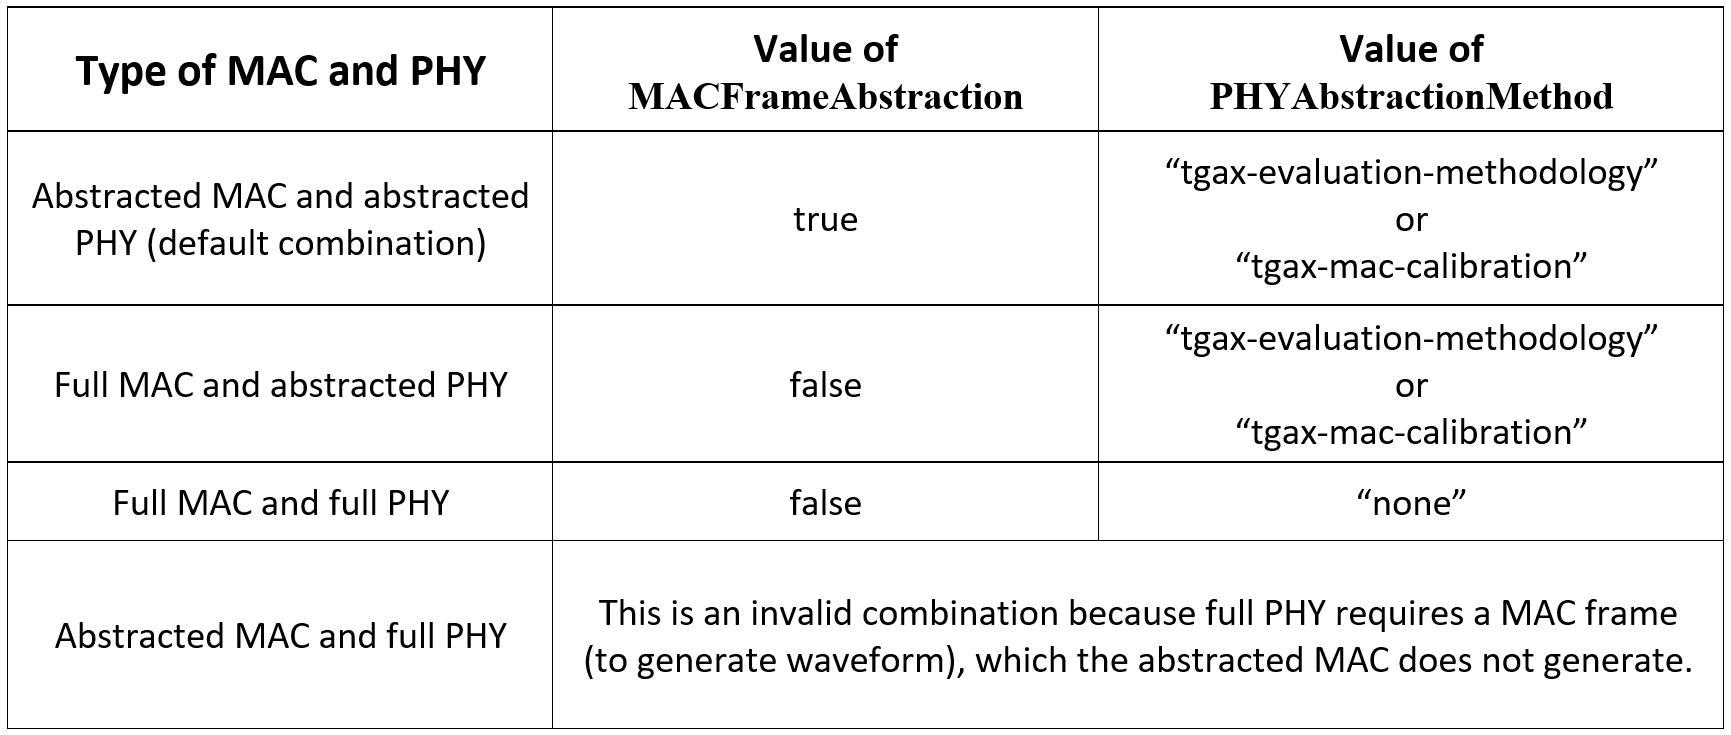

% Use wlanNode() function to instantiate the AP using the configuration you
% have just created
% Name the variable "AP"
% Note : use the following values to start with
% "DeviceConfig",APCfg
% "Position", AP_pos
% "PHYAbstractionMethod","tgax-evaluation-methodology"
% "MACFrameAbstraction",false

### [Help on creating WLAN node ](https://www.mathworks.com/help/wlan/ref/wlannode.html)

% <enter code below>
% AP = 

### Create the STA

- 802.11n type

- Similar as the creation of the AP

- Code is provided for you

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ... 
    "AggregateHTMPDU",false, ...
    "MCS",6);

STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

# Task #3/4 Associate AP with STA

### Define traffic type

- Beacon Only (default)

- Bidirectional

- DL

- UL 

trafficType = "off"

`Note`` : `

- `As of now, Full buffer configuration generates traffic in AC0.`

- `As full buffer configuration generates AC0(Best Effort) traffic, you can still instantiate traffic of other ACs (AC1(Background), AC2(Video), AC3(`Voice`))  `

- `Traffic generation is implementation dependent and not part of EDCA and QoS. EDCA and QoS define how the generated traffic is differentiated, prioritized, and queued. `

- `Full buffer just represents a traffic pattern where a node always has data to send at any point of time. This pattern can be applied for any Access Category, but we support it for only AC0 in our simulation.`

% Use associateStations() function to define associations between AP's and STA's
% Hint: Click the link below and and see the "Syntax" section.

### [Help on Associating Station ](https://www.mathworks.com/help/wlan/ref/wlannode.associatestations.html)

% AssociateStations is a method of the wlanNode object
% Note : please use "FullBufferTraffic" = trafficType in the function call

% <enter code below>
% 

#### **Add nodes to the network **

nodes = [AP, STA];
addNodes(networkSimulator,nodes)

#### Enable packet visualization

enablePacketVisualization = true; 
if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end

#### Add channel model to the simulator

channelModel = "FSPL";
if strcmp(channelModel,"TGAX")
    channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
    addChannelModel(networkSimulator,channel.ChannelFcn);
end

#### Run the simulation

- WirelessNetworkSimulator is an event-driven simulator

- use the run() method to start the simulation

% Create node performance visualization object
perfViewerObj = hPerformanceViewer(nodes,simulationTime);
run(networkSimulator,simulationTime)

# Task #4/4 Display statistics at AP

% Use statistics() function to get statistics (APP, MAC, PHY) for AP and STA
% Create a variable names APStatistics 
% Hint:  click the link below see the "Syntax" section.

### [Help on statistics](https://www.mathworks.com/help/wlan/ref/wlannode.statistics.html)

% <enter code below>
% APStatistics = 

#### APP layer statistics

APStatistics.App

#### MAC layer Statistics

APStatistics.MAC

#### Ability to extract a specific element :

APStatistics.MAC.TransmittedBeaconFrames

#### PHY layer Statistics

APStatistics.PHY

#### Explore statistics at the STA

STAStatistics = statistics(STA);
STAStatistics.MAC
STAStatistics.MAC.ReceivedBeaconFrames
STAStatistics.PHY

#### Calculate throughput, packet loss ratio,latency at nodes 

% Calculate throughput (Mbps) at Nodes
throughputs = throughput(perfViewerObj,[nodes(:).ID])
% Calculate packet loss ratio at Nodes
packetLossRatio = packetLossRatio(perfViewerObj,[nodes(:).ID])
% Calculate Latency (Seconds) at Nodes
averageReceiveLatency = averageReceiveLatency(perfViewerObj,[nodes(:).ID])

#### Suggested Experiment:

**#1 Set** `trafficType` **to** `DL`, **run the simulation, and see the statistics.**

**#2 Set** `trafficType` **to** `Bidirectional`, **run the simulation, and see the statistics.**

**#3 Set** `channelModel` **to** `TGAX`, **run the simulation, and see the statistics. Pay attention to packet loss ratio and other metrics **

### Further Exploration

- [https://www.mathworks.com/help/releases/R2024b/wlan/ug/getting-started-with-wlan-system-level-simulation-in-matlab.html](https://www.mathworks.com/help/releases/R2024b/wlan/ug/getting-started-with-wlan-system-level-simulation-in-matlab.html)